Eddie Kinyon    |    6/20/2021

**Problem Setup:**

mpm addpath

mpm: Adding mgds to MATLAB path



x = linspace(0,450,1000);
y = linspace(0,350,1000);
[XCoords,YCoords] = meshgrid(x,y);

idealMask = ones(size(XCoords));
output = ones(size(XCoords));

**Absorber Regions:**

heightPt_b = 0;
thicknessPt = 10; % add slider
thicknessMo = 20; % add slider
heightMo = heightPt_b + thicknessPt;
heightPt_t = thicknessPt + heightMo;

absorb_1 = [75, 175];
absorb_2 = [175, 175];
absorb_3 = [275, 175];
absorb_4 = [375, 175];

[wavePt_1_t, mask_Pt_1_t] = createRectangleTransmissionCopy(XCoords, YCoords, absorb_1, heightPt_t, [50 350 thicknessPt], 'Pt');
[wave_Mo_1, mask_Mo_1] = createRectangleTransmissionCopy(XCoords, YCoords, absorb_1, heightMo, [50 350 thicknessMo], 'Mo');
[wave_Pt_1_b, maskask_Pt_1_b] = createRectangleTransmissionCopy(XCoords, YCoords, absorb_1, heightPt_b, [50 350 thicknessPt], 'Pt');

[wave_Pt_2_t, mask_Pt_2_t] = createRectangleTransmissionCopy(XCoords, YCoords, absorb_2, heightPt_t, [50 350 thicknessPt], 'Pt');
[wave_Mo_2, mask_Mo_2] = createRectangleTransmissionCopy(XCoords, YCoords, absorb_2, heightMo, [50 350 thicknessMo], 'Mo');
[wave_Pt_2_b, mask_Pt_2_b] = createRectangleTransmissionCopy(XCoords, YCoords, absorb_2, heightPt_b, [50 350 thicknessPt], 'Pt');

[wave_Pt_3_t, mask_Pt_3_t] = createRectangleTransmissionCopy(XCoords, YCoords, absorb_3, heightPt_t, [50 350 thicknessPt], 'Pt');
[wave_Mo_3, mask_Mo_3] = createRectangleTransmissionCopy(XCoords, YCoords, absorb_3, heightMo, [50 350 thicknessMo], 'Mo');
[wave_Pt_3_b, mask_Pt_3_b] = createRectangleTransmissionCopy(XCoords, YCoords, absorb_3, heightPt_b, [50 350 thicknessPt], 'Pt');

[wave_Pt_4_t, mask_Pt_4_t] = createRectangleTransmissionCopy(XCoords, YCoords, absorb_4, heightPt_t, [50 350 thicknessPt], 'Pt');
[wave_Mo_4, mask_Mo_4] = createRectangleTransmissionCopy(XCoords, YCoords, absorb_4, heightMo, [50 350 thicknessMo], 'Mo');
[wave_Pt_4_b, mask_Pt_4_b] = createRectangleTransmissionCopy(XCoords, YCoords, absorb_4, heightPt_b, [50 350 thicknessPt], 'Pt');

wave_Pt_t = wavePt_1_t.*wave_Pt_2_t.*wave_Pt_3_t.*wave_Pt_4_t;
mask_Pt_t = mask_Pt_1_t.*mask_Pt_2_t.*mask_Pt_3_b.*mask_Pt_4_b;

wave_Mo = wave_Mo_1.*wave_Mo_2.*wave_Mo_3.*wave_Mo_4;
mask_Mo = mask_Mo_1.*mask_Mo_2.*mask_Mo_3.*mask_Mo_4;

wave_Pt_b = wave_Pt_1_b.*wave_Pt_2_b.*wave_Pt_3_b.*wave_Pt_4_b;
mask_Pt_b = maskask_Pt_1_b.*mask_Pt_2_b.*mask_Pt_3_b.*mask_Pt_4_b;

**Output and Ideal Mask**

wave = wave_Pt_t.*wave_Mo.*wave_Pt_b;
mask = mask_Pt_t.*mask_Mo.*mask_Pt_b;

**Image Simulation**

lambda_nm = 13.5;
size_um = [450, 350];
NA = 0.33;
intens = imageSim(wave, size_um, lambda_nm, NA);

**Image Deprotection**

imgIntens = (abs(wave)).^2;
sz_um = [.400, .400];
dose_mJpcm2 = 50;
blur_nm = 10;
rate = 40;
threshold = 0.50;
latent = imageToDeprotection(imgIntens, sz_um, dose_mJpcm2, blur_nm, rate, threshold);

mpm: Adding mgds to MATLAB path


**Plotting : unsure if plotting correct functions **

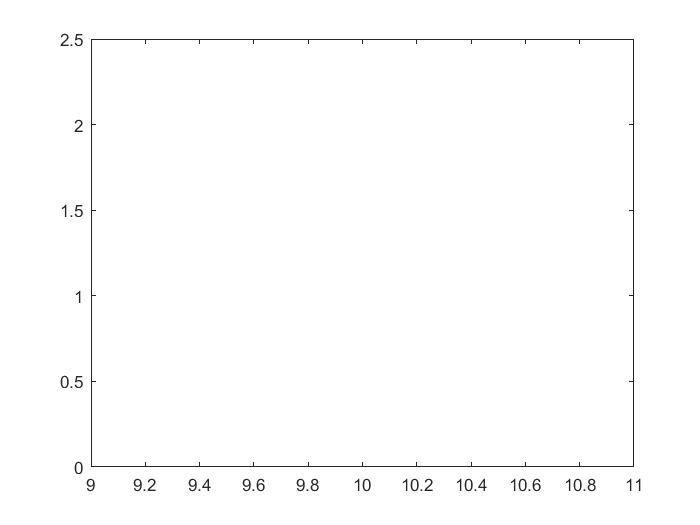

% intenslow = min(intens,[],'all');
% intenshigh = max(intens,[],'all');
% contrastin = (intenshigh-intenslow);
% plot(10, contrastin);